# Control and Simulate Multiple Warehouse Robots

This example shows how to control and simulate multiple robots working in a warehouse facility or distribution center. The robots drive around the facility picking up packages and delivering them to stations for storing or processing. This example builds on top of the [Execute Tasks for a Warehouse Robot](docid:robotics_ug.mw_0c16e017-b9af-4684-94d7-ca6430f0aec3) example, which drives a single robot around the same facility.

This package-sorting scenario can be modeled in Simulink® using Stateflow charts and Robotics System Toolbox™ algorithm blocks. A **Central Scheduler** sends commands to robots to pick up packages from the *loading station* and deliver them to a specific *unloading station*. The **Robot Controller** plans the trajectory based on the locations of the loading and unloading stations, and generates velocity commands for the robot. These commands are fed to the **Plant**, which contains a differential-drive robot model for executing the velocity commands and returning ground-truth poses of the robot. The poses are fed back to the scheduler and controller for tracking the robot status. This workflow is done for a group of 5 robots, which are all scheduled, tracked, and modeled simultaneously.

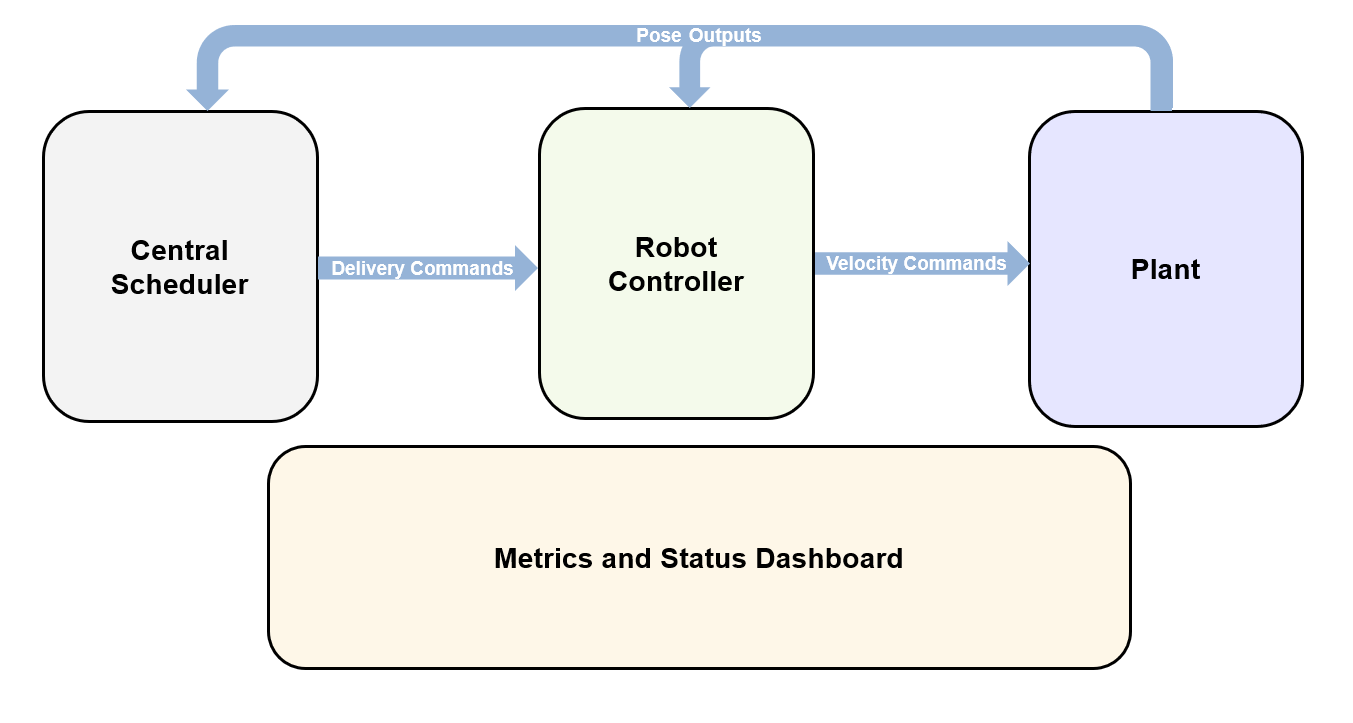

The provided Simulink model, `multiRobotExampleModel`, models the above described scenario.

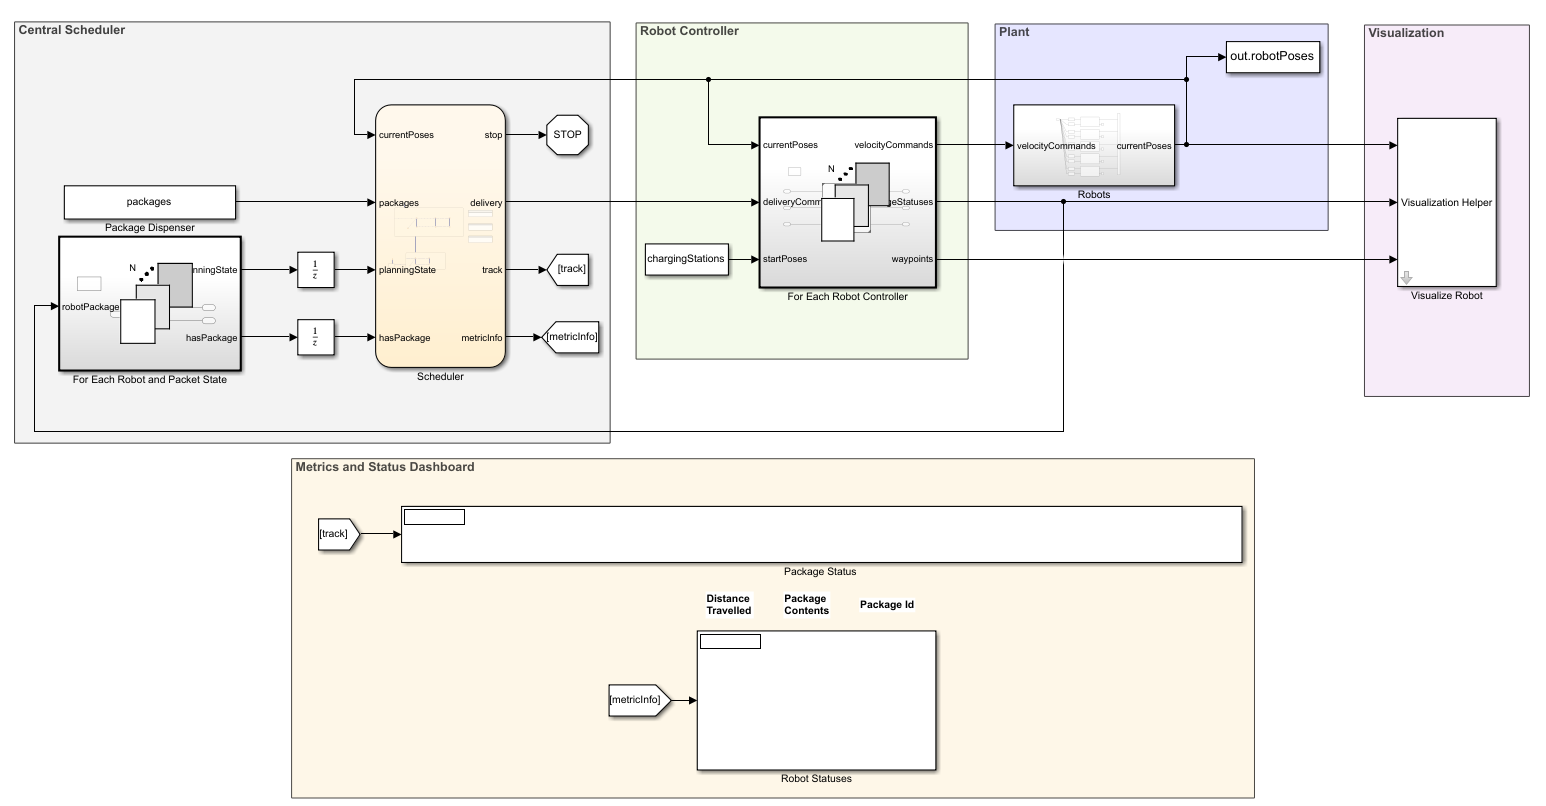

### Central Scheduler

The Central Scheduler uses a Stateflow chart to handle package allocation to the robots from the **Package Dispenser**. Each robot can carry one package at a time and is instructed to go from the loading to an unloading station based on the required location for each package. The scheduler also tracks the status of the packages and robots and updates the **Status Dashboard**. Based on robot poses, the scheduler also sends stop commands to one robot when it detects an imminent collision. This behavior can allow the robots to run local obstacle avoidance if available.

The **For Each Robot and Package State **subsystem is a [For-Each Subsystem](docid:simulink_ref.buiyr7s-1) which processes an array of buses for tracking the robot and package states as  `RobotPackageStatus` bus object. This makes it easy to update this model for varying number of robots. For more information about processing arrays of buses using a For-Each Subsystem, see [Work with Array of Buses Signals](docid:simulink_ug.bvg13ca). 

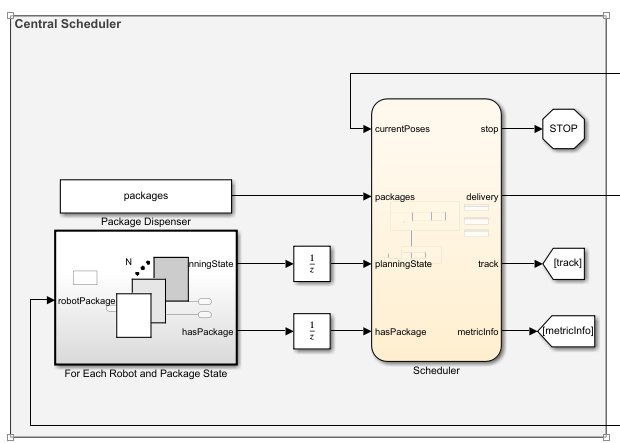

#### Scheduler

The following schematic details the signal values of the **Scheduler** Stateflow chart. 

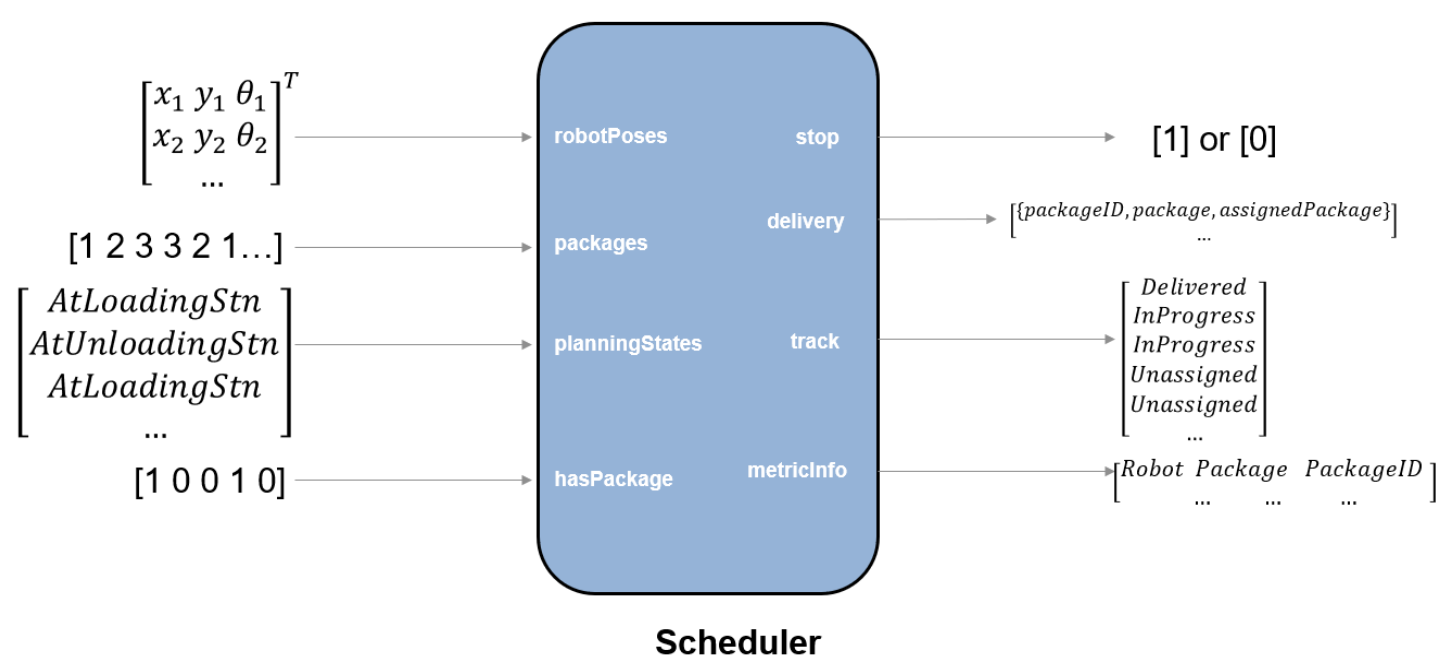

### Robot Controller

The **Robot Controller** uses a [For-Each Subsystem](docid:simulink_ref.buiyr7s-1) to generate an array of robot controllers for your 5 robots.

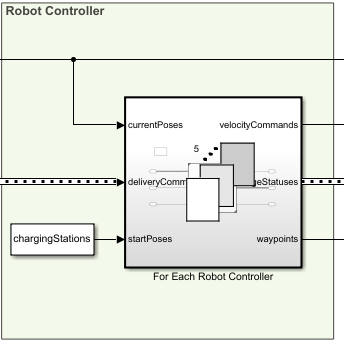

The following schematic details the type of signal values associated with the **For Each Robot Controller**.

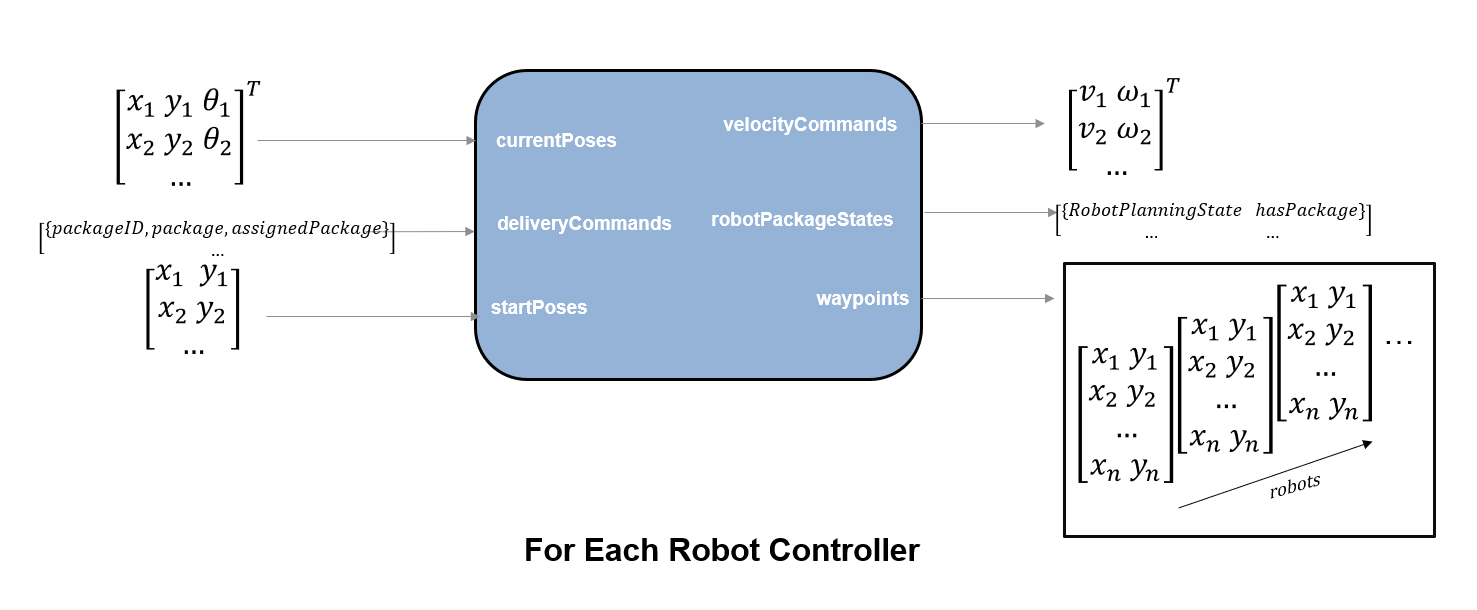

Each robot controller has the following inputs and outputs.

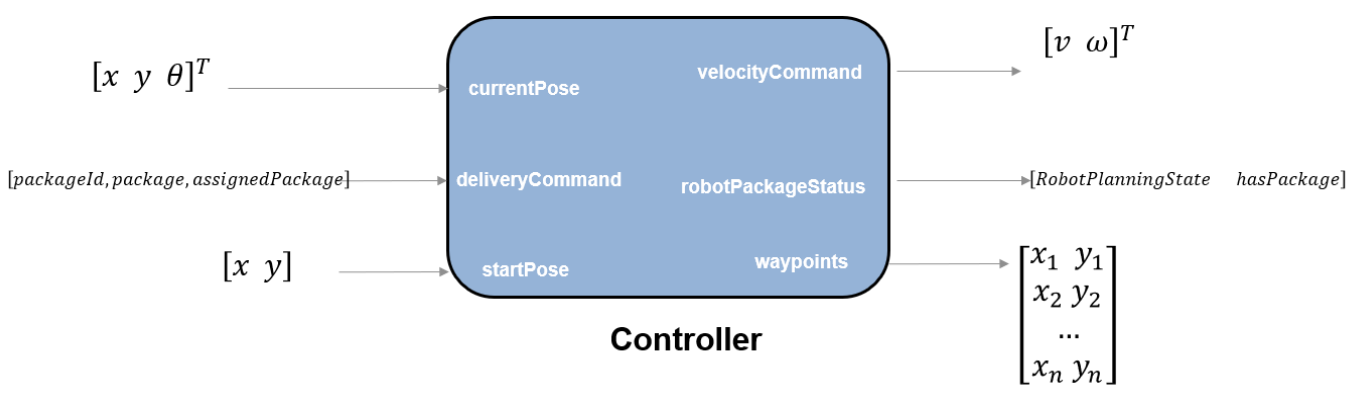

The controller takes delivery commands, which contains the package information, and plans a path for delivering it someone in the warehouse using `mobileRobotPRM`. The **Pure Pursuit** block takes this path and generates velocity commands for visiting each waypoint. Also, the status of the robot and packages get updated when the robot reaches its goal. Each robot also has its own internal scheduler that tells them the location of unloading stations based on the package information, and sends them back to the loading station when they drop off a package. 

The robot controller model uses the same model, `warehouseTasksRobotSimulationModel`, shown in [Execute Tasks for a Warehouse Robot](docid:robotics_ug.mw_0c16e017-b9af-4684-94d7-ca6430f0aec3).

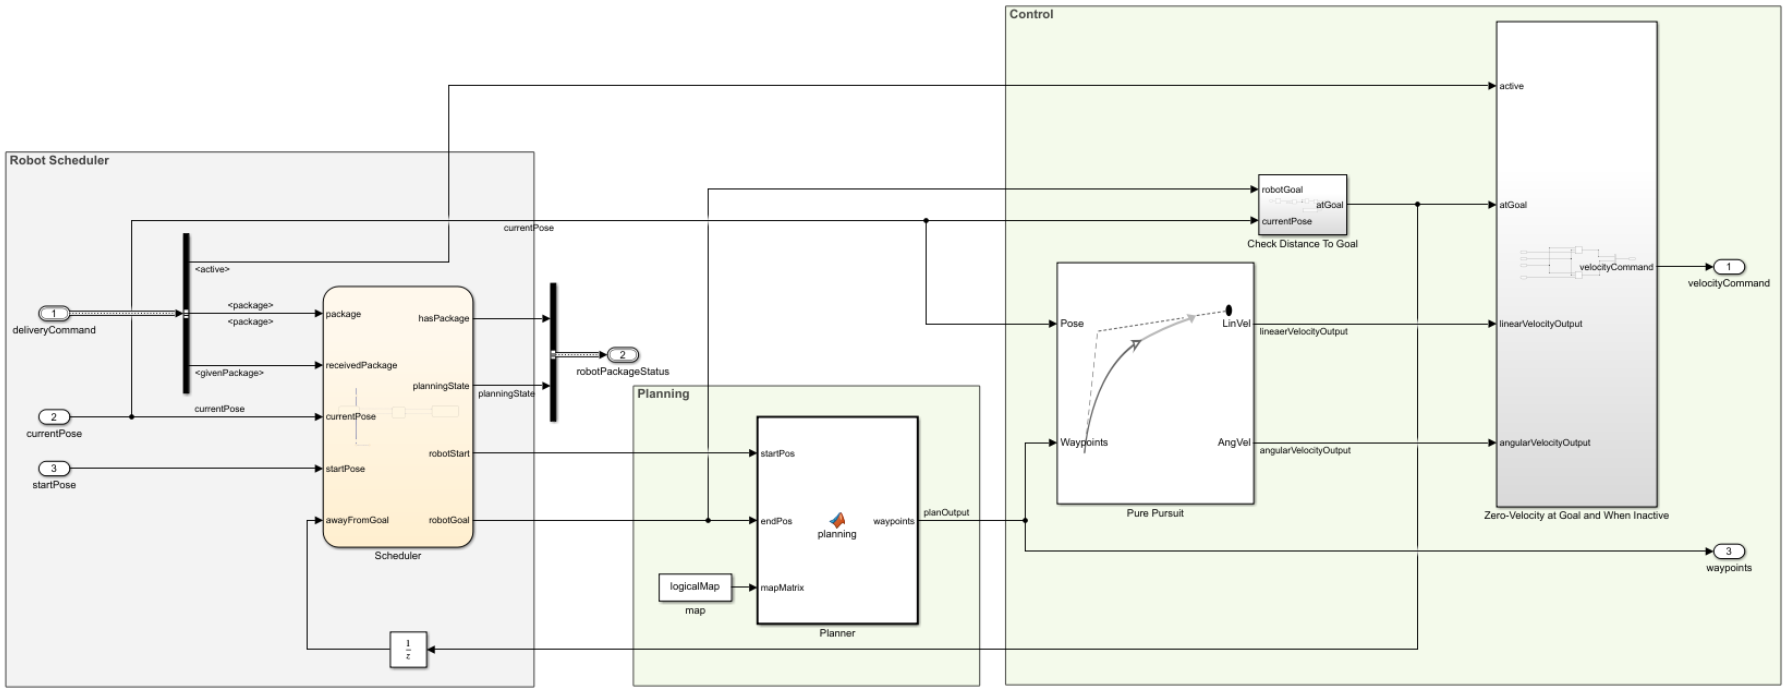

### Plant

The **Plant** subsystem uses a **Differential Drive Kinematic Model** block to model the motion of the robots. 

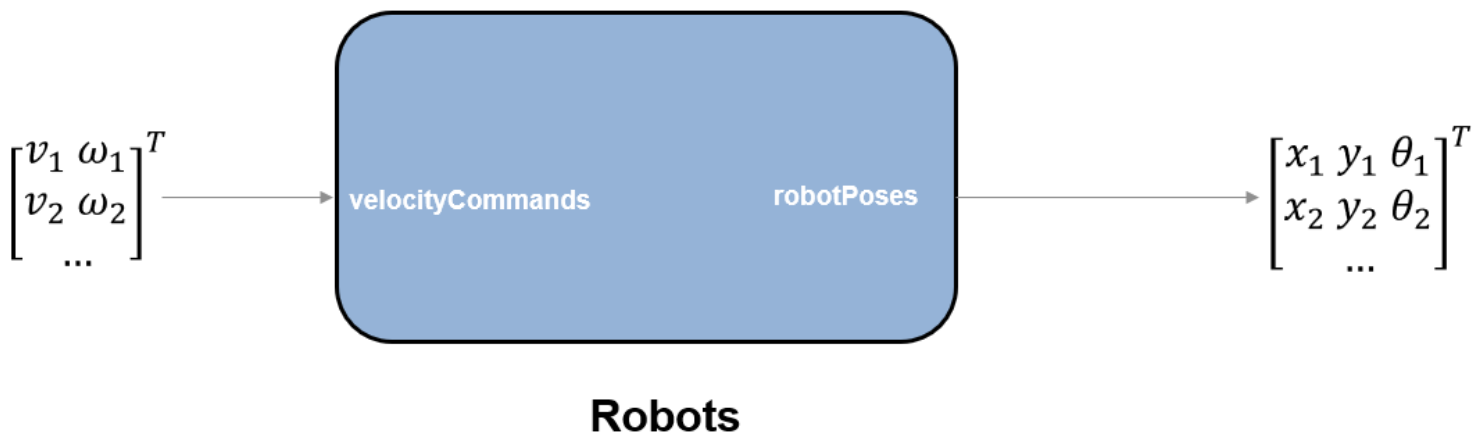

## Model Setup 

Begin to setup various variables in MATLAB® for the model.

#### Defining the Warehouse Environment

A logical type matrix, `logicalMap` represents the occupancy map of the warehouse. The warehouse contains obstacles representing walls, shelves, and other processing stations. Loading, unloading, and charging stations are also given in *xy*-coordinates.

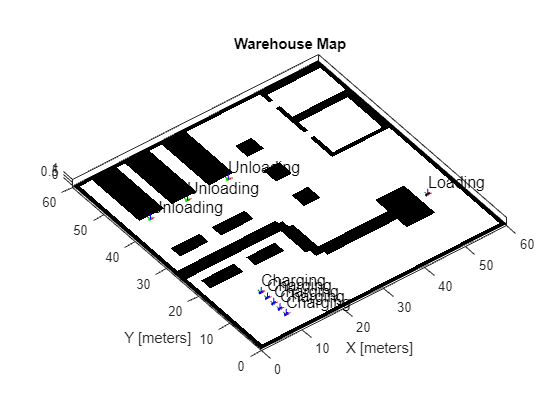

load multiRobotWarehouseMap.mat logicalMap loadingStation unloadingStations chargingStations
warehouseFig = figure('Name', 'Warehouse Setting', 'Units',"normalized", 'OuterPosition',[0 0 1 1]);
visualizeWarehouse(warehouseFig, logicalMap, chargingStations, unloadingStations, loadingStation);

#### Checking occupancy at stations

Ensure that the stations are not occupied in the map.

map = binaryOccupancyMap(logicalMap);
if(any(checkOccupancy(map, [chargingStations; loadingStation; unloadingStations])))
    error("At least one of the station locations is occupied in the map.")
end

### Central Scheduler

The **Central Scheduler** requires the knowledge of the packages that are to be delivered so as to send the delivery commands to the robot controllers. 

#### Defining Packages

Packages are given as an array of index numbers of the various unloading stations that the packages are supposed to be delivered to. Because this example has three unloading stations, a valid package can take a value of 1, 2, or 3.  

load packages.mat packages
packages

packages =      3     2     1     2     3     1     1     1     2     3     1


#### Number of Robots 

The number of robots is used to determine the sizes of the various signals in the initialization of the **Scheduler** Stateflow chart

numRobots = size(chargingStations, 1); % Each robot has its own charging station;

### Collision Detection and Goal-Reached Threshold 

The **Central Scheduler** and the **Robot Controller** use certain thresholds for collision detection, `collisionThresh`, and a goal-reached condition, `awayFromGoalThresh`.

Collision detection ensures that for any pair of robots within a certain distance-threshold, the robot with a lower index should be allowed to move while the other robot should stop (zero-velocity command). The still moving robot should be able to avoid local static obstacles in their path. You could achieve this with another low-level controller like the [**Vector Field Histogram**](docid:nav_ref.bvam7nc) block.

The goal-reached condition occurs if the robot is within a distance threshold, `awayFromGoalThresh`, from the goal location.

load exampleMultiRobotParams.mat awayFromGoalThresh collisionThresh

### Bus Objects

The `RobotDeliverCommand` and `RobotPackageStatus` bus objects are used to pass robot-package allocations between the **Central Scheduler** and the **Robot Controller**.

load warehouseRobotBusObjects.mat RobotDeliverCommand RobotPackageStatus

## Simulation

Open the Simulink model.

%open_system("multiRobotExampleModel.slx")

%mode: 0 - normal operation, 1 - small fault, 2 - large fault

mode = 2;

mode = 2

Run the simulation. You should see the robots drive plan paths and deliver packages.

out = sim('multiRobotExampleModel');

### Searching for referenced models in model 'multiRobotExampleModel'.
### Found 1 model references to update.
### Starting serial model reference simulation build.
### Model reference simulation target for robotController is up to date.

Build Summary

0 of 1 models built (1 models already up to date)
Build duration: 0h 0m 3.5633s


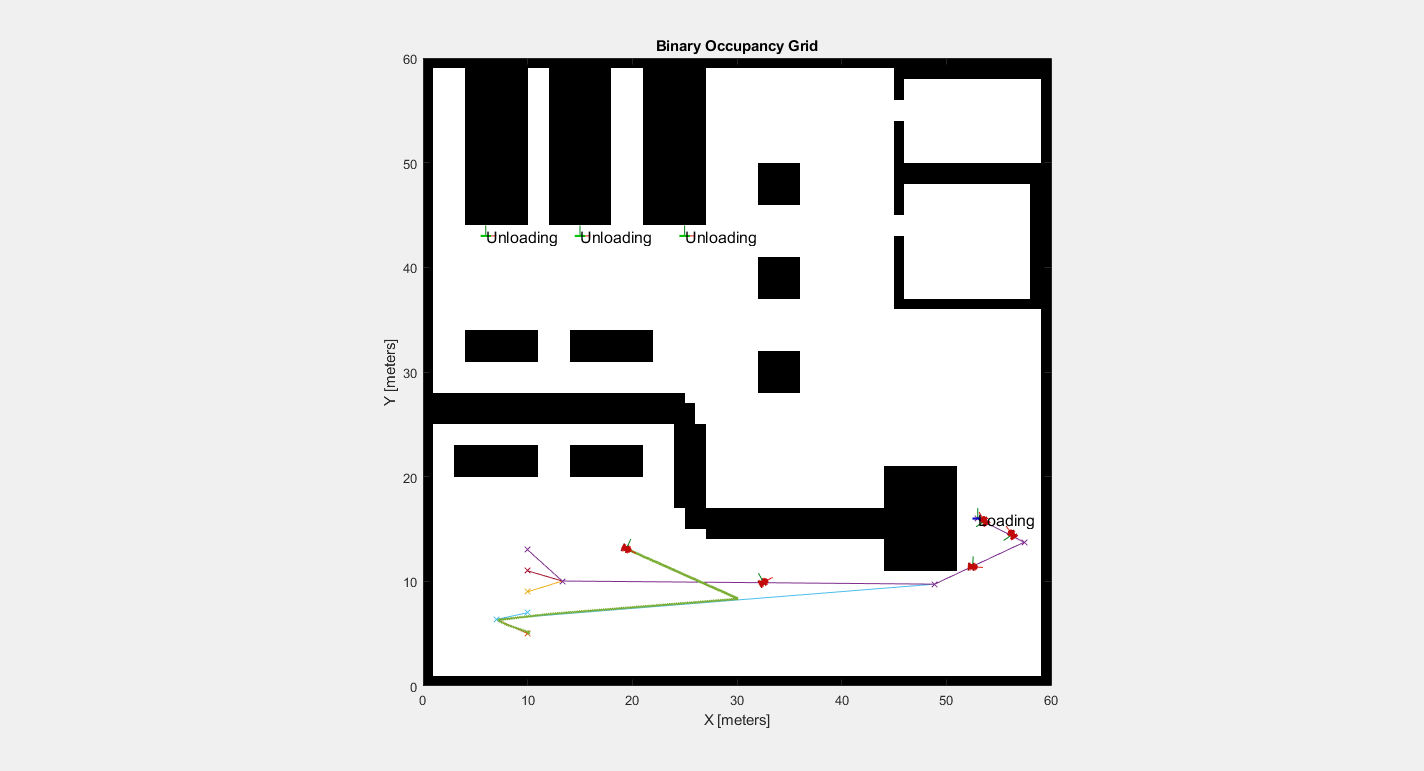

hold on
view(2)
plot(squeeze(out.robotPoses(1,1,:)),squeeze(out.robotPoses(2,1,:)), 'LineWidth', 2)

%%

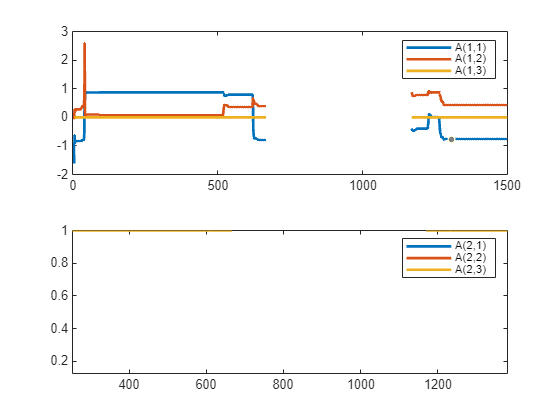

f = figure;
subplot(2,1,1)
plot(out.A.Time, out.A.Data(1:3,:),'Linewidth', 2)
legend('A(1,1)', 'A(1,2)', 'A(1,3)')
f.Position = [1 1 500 450];

subplot(2,1,2)
plot(out.A.Time, out.A.Data(4:6,:),'Linewidth', 2)
legend('A(2,1)', 'A(2,2)', 'A(2,3)')